% Experimental values
gam=35*10^(-3); % Surface tension
th=2*pi/6; % Theta contact angle
mu=20*10^(-3); % Viscosity
aa=10^(-6); % Appoximate radius of the specific colloid in ink 
kBT=4*10^(-21); % Boltzmann Const times room temperature
Dt=aa^2/(6*pi); % Diffusion of the colloid (Einstein relation)
hp=10^(-6); % This is an assumed dimensional precursor height in m

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet

tfinal = 10^5; % final time >> 1
t0 = 1e-6;% initial time << 1


c1 = 0.0010;  
c2 = 0.0196;

c3 = 0.0013;
c4 = 0.0108;

% tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift

var = [A;N;k;y0]; 
% Set time span
tSpan = [1e-6 tfinal]; 
% Creating test matrix to soolve ODE
D1 = full(gallery('tridiag',N,-1,0,1));
D1(N,1)=1;D1(1,N)=-1;
D1 = D1/(2*dx);
D1 = sparse(D1); % D1
D2 = full(gallery('tridiag',N,1,-2,1));
D2(N,1)=1;D2(1,N)=1;
D2 = D2/dx^2;
D2 = sparse(D2);

times = logspace(-6,5,4);
% hhh_1 = hFinalRegion([19;0.0044;-0.0951],X,var,D1,D2,tSpan);
hhh_2 = hFinalRegion([19;0.0044;-0.0951],X,var,D1,D2,tSpan);
hhh_3 = hFinalRegion([20;0.0044;-0.0951],X,var,D1,D2,tSpan);
hhh_4 = hFinalRegion([21;0.0044;-0.0951],X,var,D1,D2,tSpan);

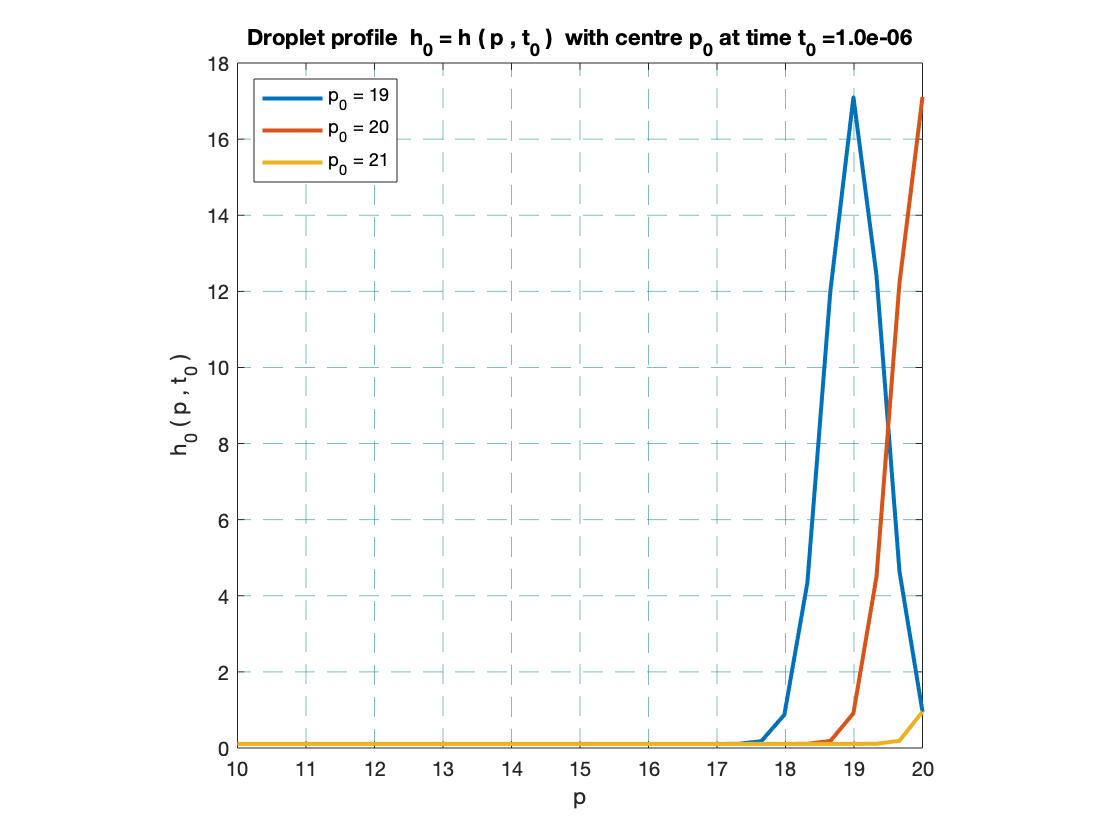

figure;
hold on
pbaspect([1 1 1]);
xlim([10 20]);
ylim([0 18]);
xlabel('p');
ylabel('h_0 ( p , t_0 )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

tit=strcat('Droplet profile  h_0 = h ( p , t_0 )  with centre p_0 at time t_0 = ',num2str(times(1),'%1.1e'));
    
ht2 = deval(hhh_2,times(1));
p2 = plot(X,ht2,'linewidth',2);
ht3 = deval(hhh_3,times(1));
p3 = plot(X,ht3,'linewidth',2);
ht4 = deval(hhh_4,times(1));
p4 = plot(X,ht4,'linewidth',2);

drawnow
legend('p_0 = 19',...
    'p_0 = 20',...
    'p_0 = 21',...
    'Location','northwest')
title(tit);
% legend(Legend,'interpreter','latex')
hold off


figure;
hold on
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 7]);
xlabel('p');
ylabel('h = h ( p_0 = 19 , t )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

Legend=cell(3,1);
for i = 1:3
    Legend{i}=strcat('time t = ',num2str(times(i+1),'%1.1e'));
    ht_2 = deval(hhh_2,times(i+1));
    p_2 = plot(X,ht_2,'linewidth',2);
end
drawnow

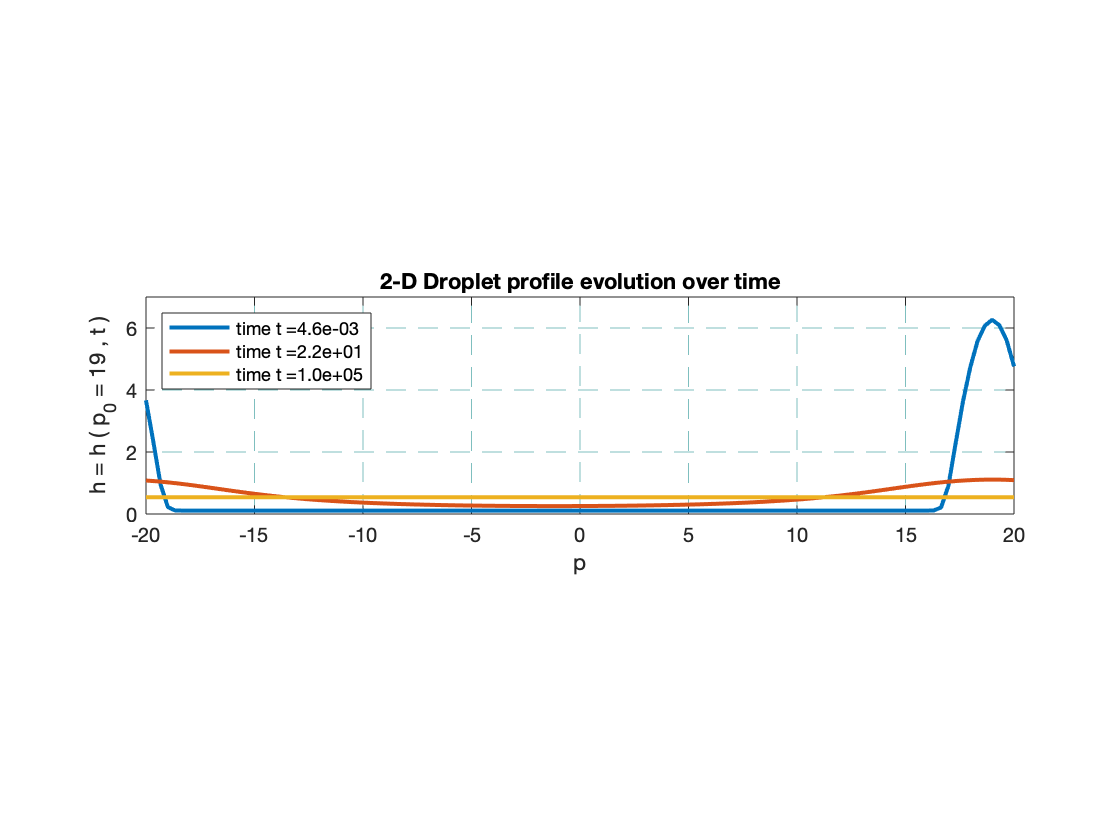

legend(Legend,...
    'Location','northwest')
title('2-D Droplet profile evolution over time');
% legend(Legend,'interpreter','latex')
hold off


figure;
hold on
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 7]);
xlabel('p');
ylabel('h = h ( p_0 = 20 , t )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

Legend=cell(3,1);
for i = 1:3
    Legend{i}=strcat('time t = ',num2str(times(i+1),'%1.1e'));
    ht_3 = deval(hhh_3,times(i+1));
    p_3 = plot(X,ht_3,'linewidth',2);
end
drawnow

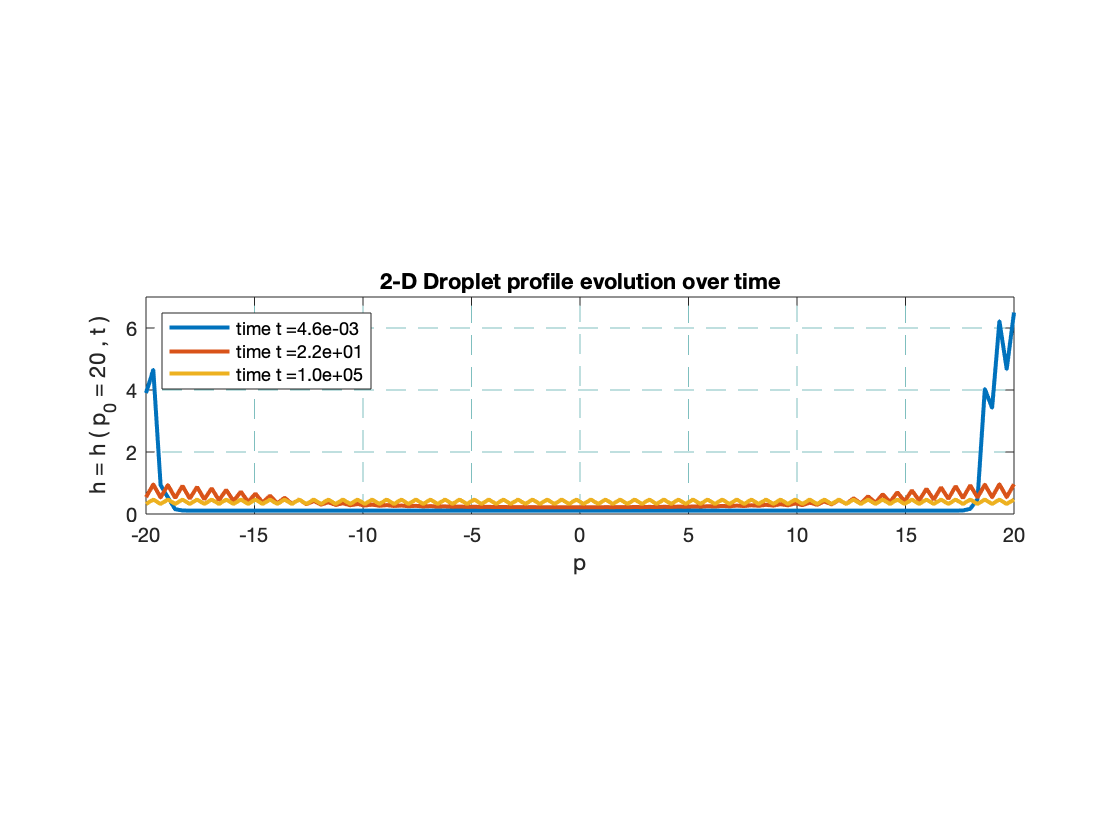

legend(Legend,...
    'Location','northwest')
title('2-D Droplet profile evolution over time');
% legend(Legend,'interpreter','latex')
hold off


figure;
hold on
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 7]);
xlabel('p');
ylabel('h = h ( p_0 = 20 , t )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

Legend=cell(3,1);
for i = 1:3
    Legend{i}=strcat('time t = ',num2str(times(i+1),'%1.1e'));
    ht_4 = deval(hhh_4,times(i+1));
    p_4 = plot(X,ht_4,'linewidth',2);
end
drawnow

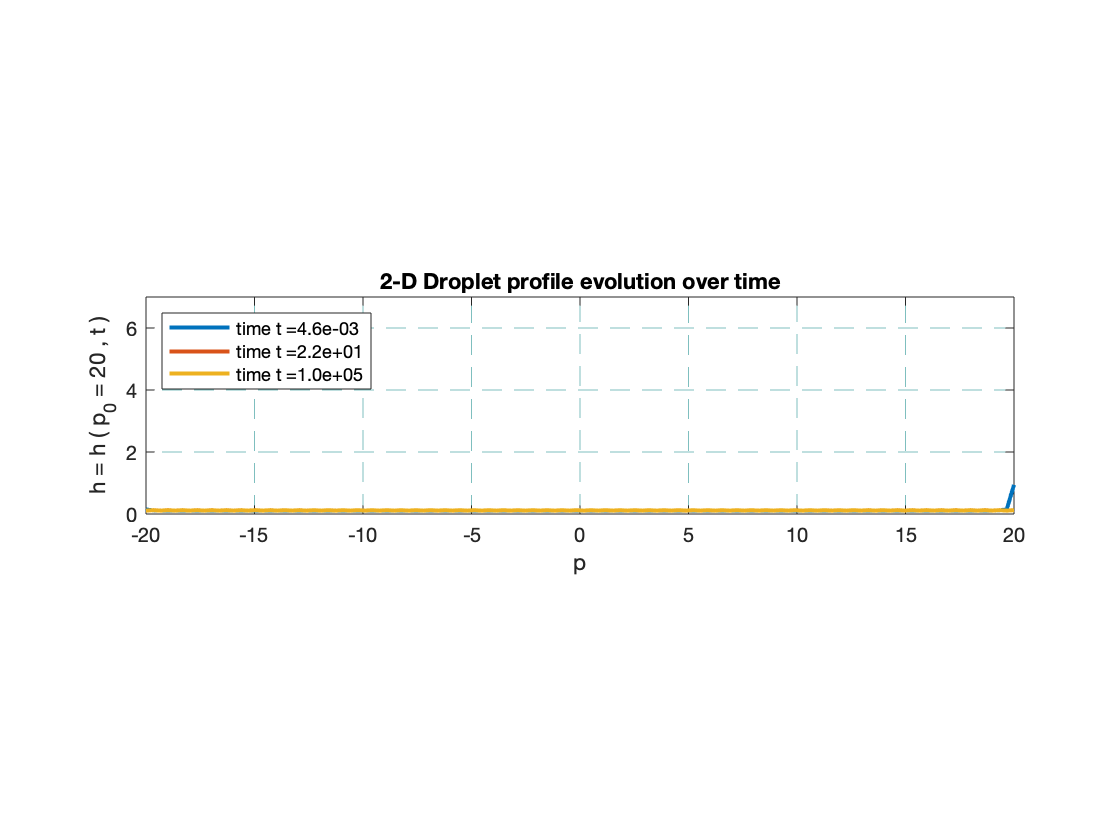

legend(Legend,...
    'Location','northwest')
title('2-D Droplet profile evolution over time');
% legend(Legend,'interpreter','latex')
hold off